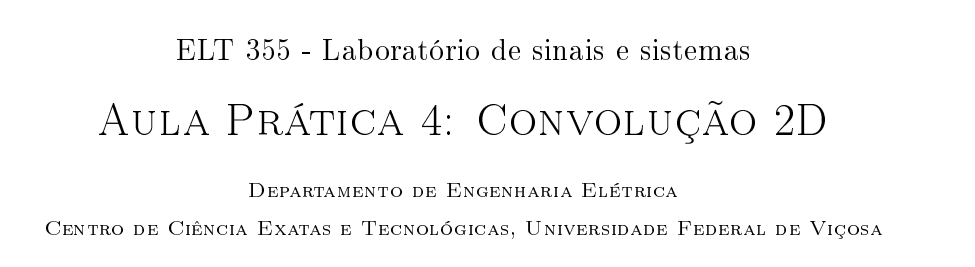

26/05/22

**Aluno:** Déric A. F. de Sales - 96718

clear all; close all; clc;

### Exercício 1: Resposta ao impulso

#### Resposta ao impulso unitário

*Para melhor entendimento do spript dado na prática, como requisitado cada linha de código será comentada.*

O primeiro comando limpa todas as variáveis do *workspace*, o segundo fecha elementos específicos que podem estarem armazenados na memória, como figuras. Já o terceiro, limpa o texto da *command window*.

clear all; close all; clc;

Definindo um vetor com elementos que vão de 0 até o elemento 19, com passo 1.

n = 0:19;

Cria a função x(n), através de um *function randle,* onde a função compara os valores do vetor n com o valor 0, retornando um vetor do mesmo tamanho de n com os resultados das comparações.

x = @(n) n==0;

ans = 1×20 logical array
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Cria os vetores "a" e "b", cada um com 3 elementos.

a = [1 -0.6 -0.16];
b = [5 0 0 ];

A função *filter(b,a,x) *computa a multiplicação de x(n) por uma razão de equações de diferenças de a e b, tal qual o seguinte:


$$Y(z) = \frac{b(1) + b(2)z^{-1} + ... + b(n_{b} + 1)z^{-n_{b}}}{1 + a(2)z^{-1} + ... + a(n_{a} + 1) z ^{-n_{a}}}$$


h = filter(b,a,x(n));

A função *stem(n,h) *plota gráficos de forma discreta.

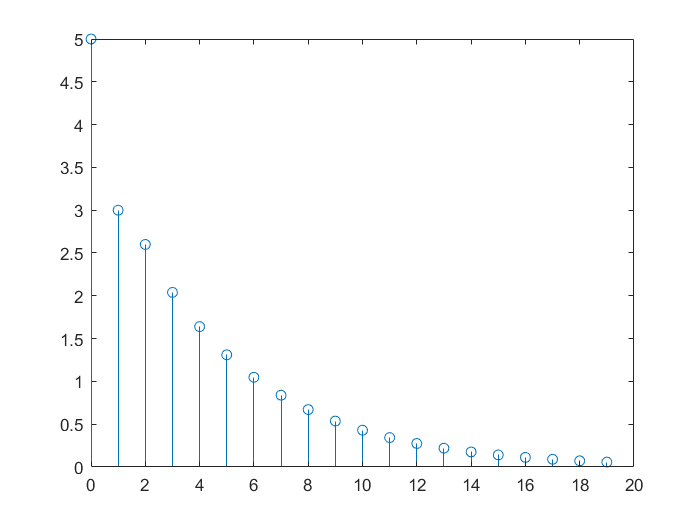

stem(n,h)

obtendo a resposta para a entrada $x[n] = u[n]$.

*obs.:* n==n é equivalente à ones(n-1)

a convolução é um filtro, função filter como aplicação de convolução para a palicação de EDO 

dado uma equação de difernças é possível simu

#### Obtendo a resposta ao impulso para a entrada $x[n] = \frac{sen[n]}{n}$.

clear all; close all; clc;

*obs.: *eps é um valor do Matlab que é aproximadamente nulo, usado aqui para que não aconteça o caso $\frac{sin(0)}{0}$, que resultaria em erro pela indeterminação matemética.

a = [1 -0.6 -0.16];
b = [5 0 0 ];

n2 = eps:19

n2 =     0.0000    1.0000    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000   10.0000   11.0000   12.0000   13.0000   14.0000   15.0000   16.0000   17.0000   18.0000   19.0000


length(n2)

ans = 20

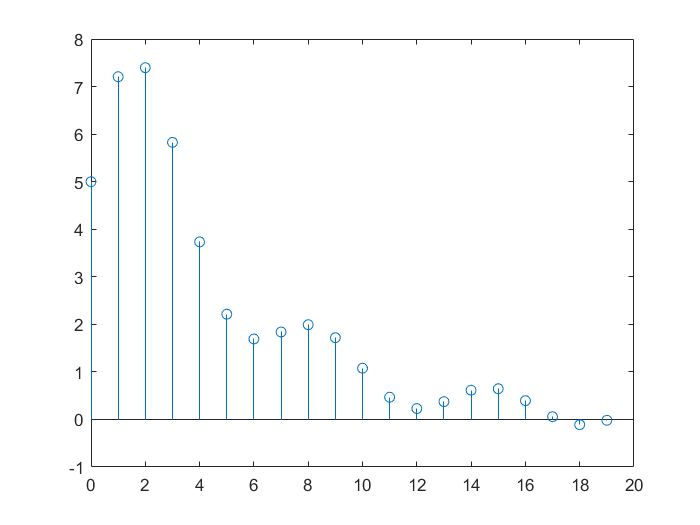

x = @(n) sin(n)/n;

X = [];
for i = 1:length(n2)
    X(i) = x(n2(i));   
end
figure()
h = filter(b,a,X);
stem(n2,h)

### Exercício 2: Implementação da convolução discreta

clear all; close all; clc;

a = [1 -0.6 -0.16];
b = [5 0 0 ];

convolucao(a,b)

ans =      5     0     0     0     0


conv(a,b)

ans =     5.0000   -3.0000   -0.8000         0         0


### Exercício 3: Convolução 2D

clear all; close all; clc;

### Funções

function res = convolucao(a,b)

    % igualando tamanho dos vetores
    a1 = [a zeros(1, length(b) )];
    b1 = [b zeros(1, length(a) )];
    
    % calculando o tamanho do vetor de resultado da convolução
    d = numel(a) + numel(b) -1;
    
    % realizando o somatório da convolução
    for k = 1:d
        y(k) = sum(a1(1,k).*fliplr(b1(1,k)) );
    end

    res = y;
end

% Tentativa frustrada de criar a função:

function res = convolucao2(A,B)

    % deixando os vetores do mesmo tamanho
    %(completando o menor com velores 0)
    lenA = length(A); % equivelentes para vetores: length(A), numel(A), size(A,2)
    lenB = length(B);
    if lenA > lenB
        diff_len = lenA-lenB;
        B = [B,zeros(1,diff_len)];       
    elseif lenB > lenA
        diff_len = lenB-lenA;
        A = [A,zeros(1,diff_len)];
    end
   
    % realizando o somatório da convolução
    Y = [];
    d = numel(A) + numel(B) - 1;
    for k = 1:d
        Y(k) = sum(A(1,k).*fliplr(B(1,k)) );
    end

    res = Y;
end